%Expt No 3: Ploting unary phase diagram for pure metals
% Prorammer Name- Sahil Kumar Patra (124MM0055)
clc
clear all
Metal= input("Enter name of Metal : ","s");
str='Phase Diagram for ';
str2=' :';
Message= [str,Metal,str2];
disp(Message);

Phase Diagram for si :


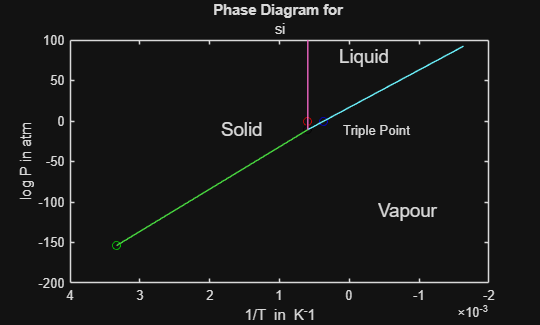

TM=input("Enter Melting Temperature of Metal (in Kelvin):");
TB=input("Enter Boiling Temperature of Metal (in Kelvin):");
HM=input("Enter Latent Heat of Melting of Metal (in Joules per mole):");
HV=input("Enter Latent Heat of Vapourising of Metal (in Joules per mole):");
R=8.314; %Universal Gas Constant in Joules per mole per kelvin
PM=1; %Atmospheric pressure
PB=1; %Atmospheric pressure
PV=1; %Atmospheric pressure
%Calculating Constant in Liquid-Vapour Equilibrium Equation
AV=PV*exp(HV/(R*TB));
TT=TM; %Taking Triple Point Temperature
%Calculating Triple Point Pressure
PT=AV*exp(-HV/(R*TT));
%Plotting Melting Point,Boiling Point, Triple Point
T=300:50:3000;
T_reci=1./T;
TM_reci=1/TM;
TB_reci=1/TB;
TT_reci=1/TT;
PM_log=log(PM);
PB_log=log(PB);
PT_log=log(PT);
%Calculation for Solid-vapour Equilibra
HS=HM+HV;
AS=PT*exp(HS/(R*TT));
RT=300;
P_RT=AS*exp(-HS/(R*RT));
RT_reci=1/RT;
P_RT_log=log(P_RT);
figure(1)
plot(TM_reci,PM_log,'ro',TB_reci,PB_log,'bo',TT_reci,PT_log,'ko',RT_reci,P_RT_log,'go');
%Plotting Phase Diagram
% For Sublimation Equilbrium
m1=(PT_log-P_RT_log)/(TT_reci-RT_reci);
X1=linspace(RT_reci,TT_reci);
Y1=P_RT_log+m1*(X1-RT_reci);
hold on
plot(X1,Y1);
%Plotting for Liquid-Vapour Equilibrium
X2=linspace(TT_reci,(TB_reci-2*10^-3));
m2=(PT_log-PB_log)/(TT_reci-TB_reci);
Y2=PT_log+m2*(X2-TT_reci);
hold on
plot(X2,Y2)
%Plotting For Solid-Liquid Equilibria
Y3=linspace(PT_log,PM_log+100);
for i= 1:100
    X3(i)=TT_reci;
end
hold on
plot(X3,Y3)
xlabel('1/T in K^-1');
ylabel('log P in atm');
title('Phase Diagram for ',Metal)
set(gca,'xdir','Reverse')
text(TT_reci-0.5*10^-3,PT_log,'Triple Point',FontSize=10)
text(TT_reci+1.25*10^-3,PT_log,'Solid',FontSize=14)
text(TT_reci-0.45*10^-3,PT_log+90,'Liquid',FontSize=14)
text(TT_reci-1*10^-3,PT_log-100,'Vapour',FontSize=14)